## Determining the ideal number of Anchor boxes

meanIoU

meanIoU = 0.8632

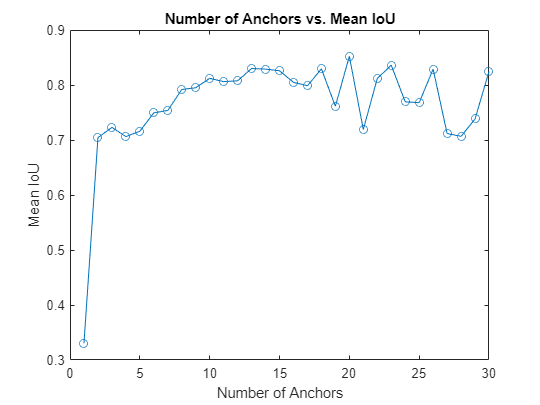

maxNumAnchors = 30;
meanIoU = zeros([maxNumAnchors,1]);
anchorBoxes = cell(maxNumAnchors, 1);
for k = 1:maxNumAnchors
    % Estimate anchors and mean IoU.
    [anchorBoxes{k},meanIoU(k)] = estimateAnchorBoxes(trainingData,k);    
end

figure
plot(1:maxNumAnchors,meanIoU,'-o')
ylabel("Mean IoU")
xlabel("Number of Anchors")
title("Number of Anchors vs. Mean IoU")